% Simulation Parameters
horizon = 1000;
dt = 0.01;
number_of_agents = 10;
d_min = 0;
d_max = 3;
v_max = 2;
v_min = 1;
bounds = [d_min, d_max, v_min, v_max];
number_of_collisions = 0;

% System Parameters
epsilon = 0.1;
r = 0.98;
d = 0.7;
h = 0.2;
phi_max = 30;
g = 9.81;
sys_params = [r, d, epsilon];

% Initialise Agents
% q, p coordinates represent positions and velocities respectively
timeVector = (0:dt:(horizon-1)*dt)';
H = zeros(size(timeVector,1));
q = zeros(size(timeVector,1), number_of_agents, 2);
p = zeros(size(timeVector,1), number_of_agents, 2);
[q(1,:,:), p(1,:,:)] = generate_agents(number_of_agents, bounds);
% q(1,:,:) = [[2,0]; [2.5,0]];
% p(1,:,:) = [[1,0]; [-1,0.01]];
temp_p = squeeze(p(1,:,:));
p_bar = mean(temp_p);
H(1) = sum(vecnorm(temp_p - p_bar,2,2).^2);


% Simulate
for i = 2:horizon
    [a, omega] = generate_force(squeeze(q(i-1,:,:)), squeeze(p(i-1,:,:)), sys_params);
    omega;
    q(i-1,:,:);
    p(i-1,:,:);
    a = reshape(a, 1, number_of_agents, 2);
    q(i,:,:) = q(i-1,:,:) + p(i-1,:,:)*dt + 1/2*a*dt*dt;
    p(i,:,:) = p(i-1,:,:) + a*dt;
    p(i,:,:) = reshape(rotate(squeeze(p(i-1,:,:)), ...
        omega*dt), 1, number_of_agents, 2);
    temp_p = squeeze(p(i,:,:));
    p_bar = mean(temp_p);
    H(i) = sum(vecnorm(temp_p - p_bar,2,2).^2);
end

omega

omega =    -0.0047
   -0.0198
   -0.0191
   -0.0775
   -0.0191
   -0.0571
   -0.0191
   -0.0191
   -0.0233
   -0.0181


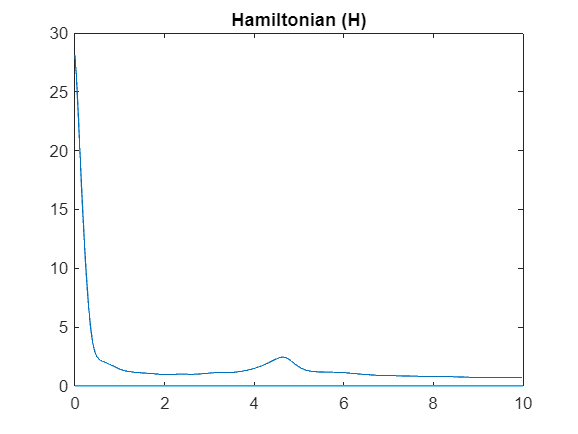


% Get Safety Stats
% stats = safety_analysis(q);
interagent_distance = vecnorm(q(:, 1, :) - q(:, 2, :), 2, 3);

% Visualise System Energy
plot(timeVector, H);
title('Hamiltonian (H)')

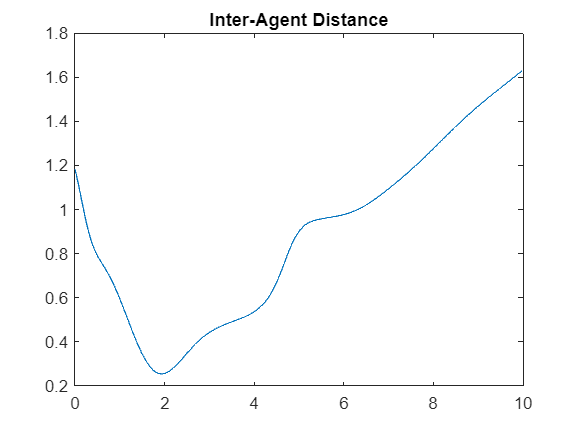


% Visualise Inter-Agent Distance
plot(timeVector, interagent_distance)
title('Inter-Agent Distance')

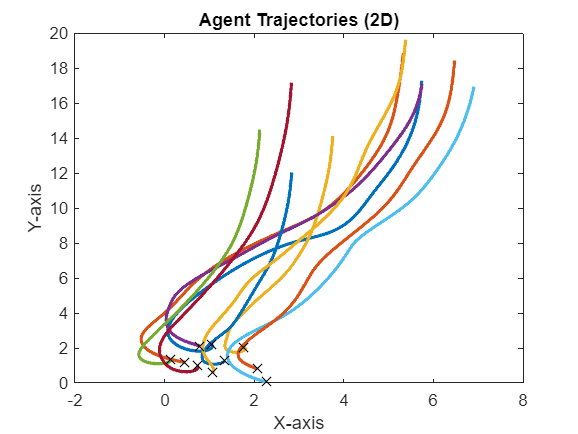


% Visualise Trajectories
plot_trajectories(q);